# Tema 6

**Pb 1.** Implementati o rutina pentru calculul valorilor polinomului de interpolare Lagrange cand se dau punctele, nodurile si valorile functiei in noduri.

x = [1900 1910 1920 1930 1940 1950 1960 1970 1980 1990 2000 2010];
y = [75.995 91.972 105.711 123.203 131.669 150.697 179.323 203.212 226.505 249.633 281.422 308.786];
xx = [1975 2018];
calculateLagrangePolynomial(x,y,xx)

ans =   214.3644 -664.3068



x = [1 1.1 1.2 1.3 1.4];
y = [f(1) f(1.1) f(1.2) f(1.3) f(1.4)];
xx = [1.25];
yy = calculateLagrangePolynomial(x,y,xx)

yy = 1.7550


errRel = norm(f(1.25) - yy) / norm(f(1.25))

errRel = 5.5456e-05

**Pb 2.** Reprezentati grafic polinoamele fundamentale cand se dau gradul si nodurile.

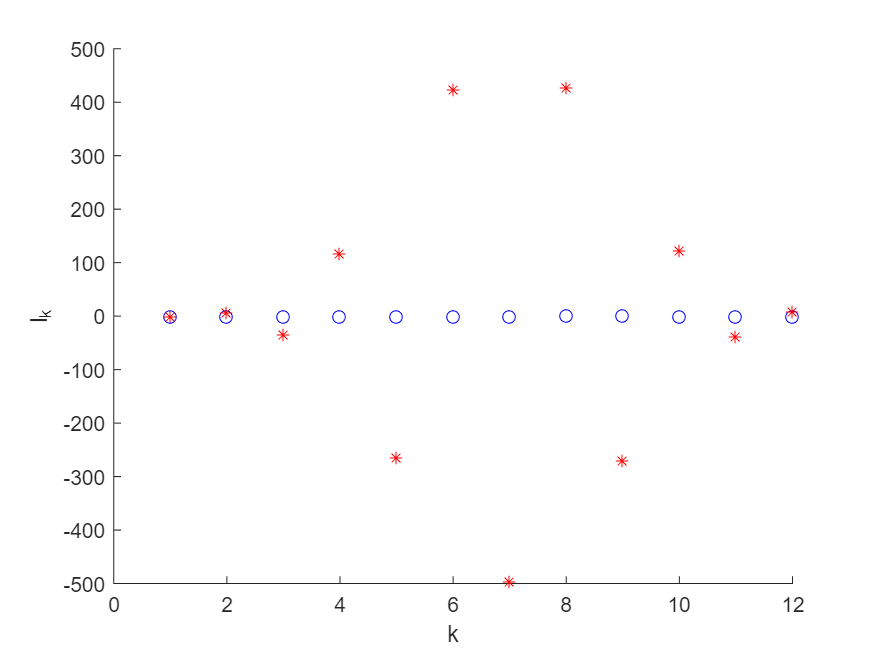

ans =   214.3644 -664.3068


x = [1900 1910 1920 1930 1940 1950 1960 1970 1980 1990 2000 2010];
y = [75.995 91.972 105.711 123.203 131.669 150.697 179.323 203.212 226.505 249.633 281.422 308.786];
xx = [1975 2018];
calculateLagrangePolynomial(x,y,xx, true)

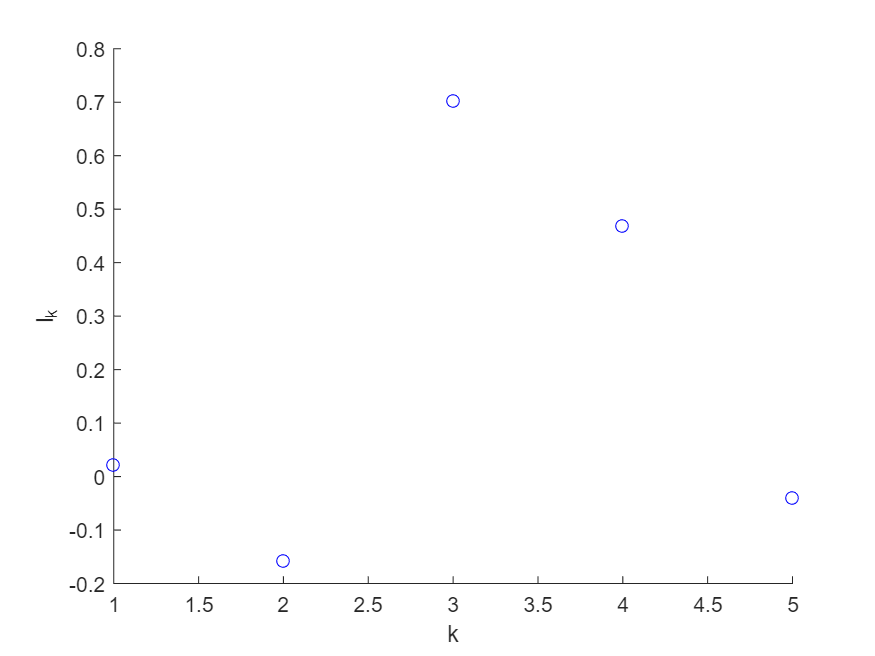

ans = 1.7550

clf;
x = [1 1.1 1.2 1.3 1.4];
y = [f(1) f(1.1) f(1.2) f(1.3) f(1.4)];
xx = [1.25];
calculateLagrangePolynomial(x,y,xx, true)

**Pb 3.** Reprezentati pe acelasi grafic f si Lmf.

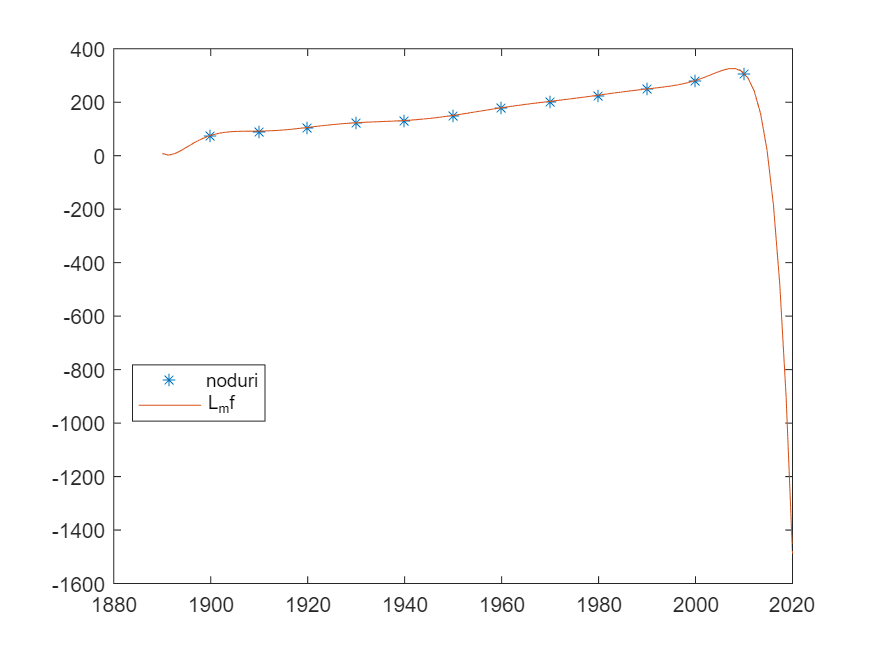

x = [1900 1910 1920 1930 1940 1950 1960 1970 1980 1990 2000 2010];
y = [75.995 91.972 105.711 123.203 131.669 150.697 179.323 203.212 226.505 249.633 281.422 308.786];
xx = linspace(1890,2020,100);
yy = calculateLagrangePolynomial(x, y, xx);
plot(x,y,'*', xx, yy)
legend('noduri','L_mf','Location', 'best')

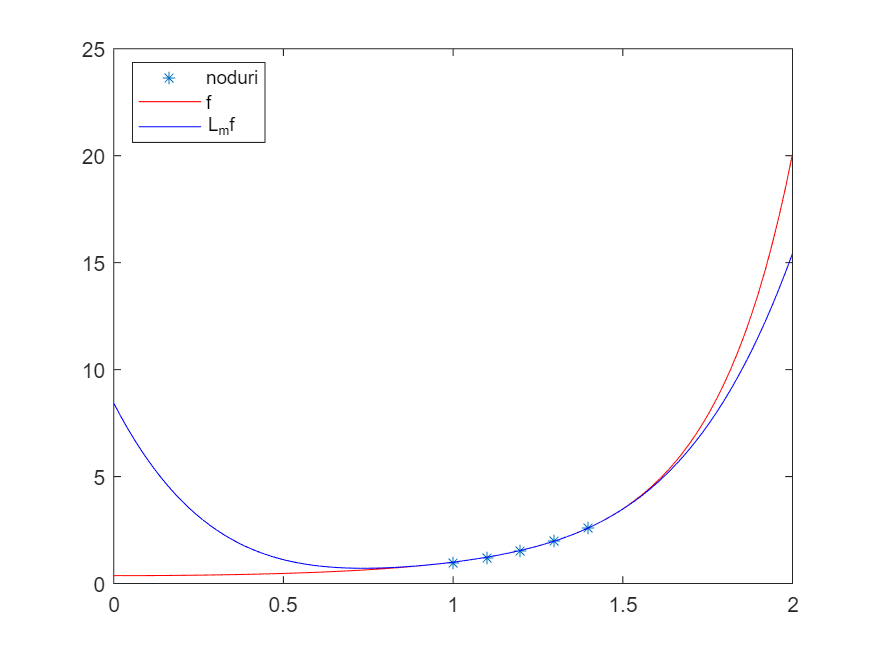


x = [1 1.1 1.2 1.3 1.4];
y = [f(1) f(1.1) f(1.2) f(1.3) f(1.4)];
xx = linspace(0,2,100);
yy = calculateLagrangePolynomial(x, y, xx);
plot(x,y,'*', xx, f(xx), 'r', xx, yy, 'b')
legend('noduri','f','L_mf','Location', 'best')

**Pb 4.** Dandu-se x, f, m si nodurile, aproximati f(x) utilizand interpolarea Lagrange.

syms t
x = [1 1.1 1.2 1.3 1.4];
y= f(x);
yy = calculateLagrangePolynomial(x,y,t)

$$yy = \frac{1748192912675783\,\left(5\,t-5\right)\,\left(5\,t-7\right)\,\left(10\,t-11\right)\,\left(10\,t-13\right)}{1125899906842624}+\frac{2940508816128297\,\left(5\,t-6\right)\,\left(\frac{5\,t}{2}-\frac{5}{2}\right)\,\left(10\,t-13\right)\,\left(\frac{10\,t}{3}-\frac{11}{3}\right)}{1125899906842624}+\left(5\,t-6\right)\,\left(\frac{5\,t}{2}-\frac{7}{2}\right)\,\left(10\,t-11\right)\,\left(\frac{10\,t}{3}-\frac{13}{3}\right)-\frac{8978896532596317\,\left(5\,t-\frac{11}{2}\right)\,\left(10\,t-12\right)\,\left(10\,t-14\right)\,\left(\frac{10\,t}{3}-\frac{10}{3}\right)}{4503599627370496}-\frac{2777996025558173\,\left(5\,t-\frac{13}{2}\right)\,\left(10\,t-10\right)\,\left(10\,t-12\right)\,\left(\frac{10\,t}{3}-\frac{14}{3}\right)}{2251799813685248}$$

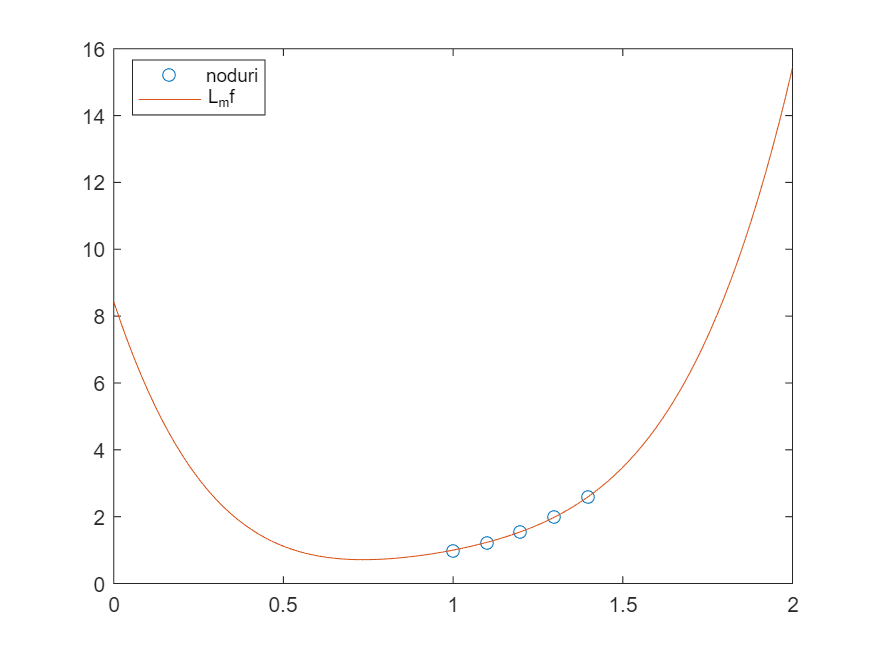

yy = subs(yy, t, linspace(0,2,100));

plot(x,y,'o', linspace(0,2,100), yy)
legend('noduri','L_mf','Location', 'best')

**Pb 5.** Implementati metoda baricentrica.

x = [1900 1910 1920 1930 1940 1950 1960 1970 1980 1990 2000 2010];
y = [75.995 91.972 105.711 123.203 131.669 150.697 179.323 203.212 226.505 249.633 281.422 308.786];
xx = [1975 2018];
c = barycentricWeigths(x);
ff = barycentricInterpolation(x,y,xx,c)

ff =   214.3644 -664.3068



x = [1 1.1 1.2 1.3 1.4];
y = [f(1) f(1.1) f(1.2) f(1.3) f(1.4)];
xx = [1.25];
c = barycentricWeigths(x);
ff = barycentricInterpolation(x,y,xx,c)

ff = 1.7550

function y=f(x)
    y = exp(x.^2 -1);
end